# PI Design with Root Locus

Design constraints.  Translate from second-order metrics to s-plane geometry.

Tr = 0.45;
omega_n = 1.8/Tr

omega_n = 4

os = 2;
zeta = -log(os/100) / sqrt(pi^2 + log(os/100)^2)

zeta = 0.7797

- 
$$T_r \le 4.5 \: \text{s} \rightarrow \omega_n \ge 4.0 \: \text{rad/s$$


- 
$$\zeta \ge 0.78$$


Plot the root locus for three different designs.

G = zpk([],[-5, -5, -8],1);

I did this as a loop, but can do each manually if desired.

pizeros = [-3, -7, -10]

pizeros =     -3    -7   -10


figure(1);
clf();
lspecs = ["r", "g", "b"]

lspecs = 1×3 string array
    "r"    "g"    "b"


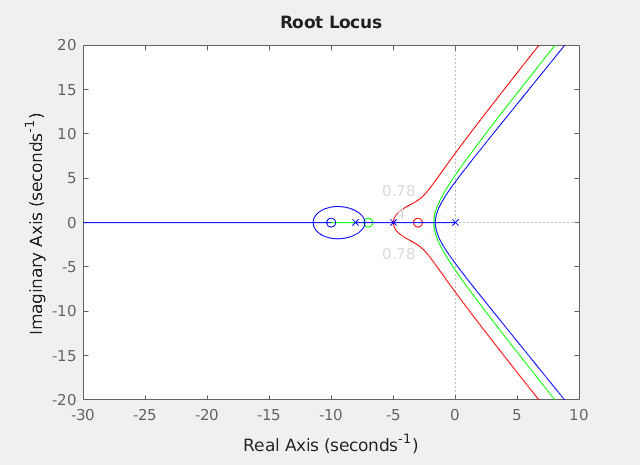

for ii = 1:length(pizeros)
    pizero = pizeros(ii);
    D = zpk([pizero],[0],1);  
    L = D * G;
    rlocusplot(L, lspecs(ii))
    hold on
   
end
sgrid(zeta, omega_n);
set(gcf,'Visible','on')

The interactive plot and sgrid commands are a bit unreliable in the live-script.  You shoudl see somethign like this...

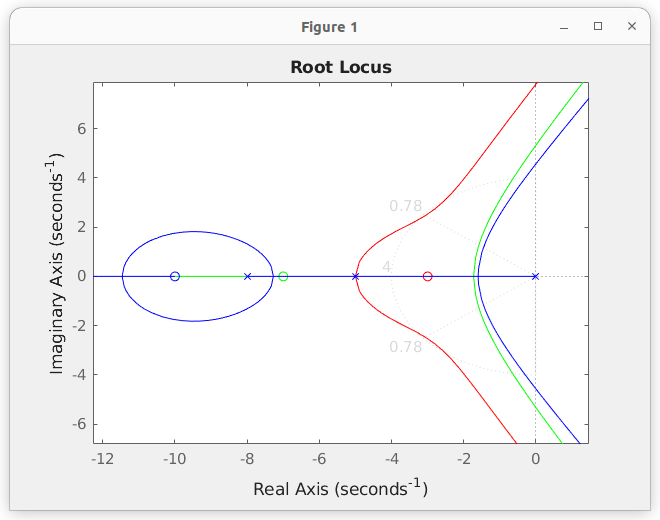

The red line in the image above, for $z = 3$, appears to be the only design that satisfies our constrains for $\zeta$and $\omega_n$.

Plot the root locus for this design.

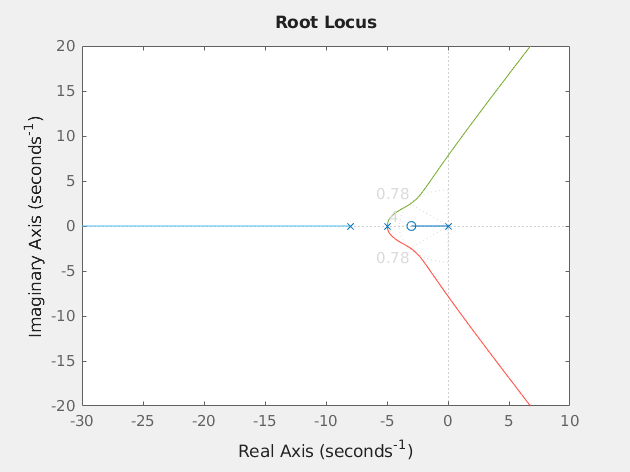

pizero = -3;
D = zpk([pizero],[0],1);  
L = D * G;
figure(2);
clf();
rlocus(L)
sgrid(zeta, omega_n);

set(gcf,'Visible','on')

Use the interactive tool to choose a gain value that should satisfy the constraints.

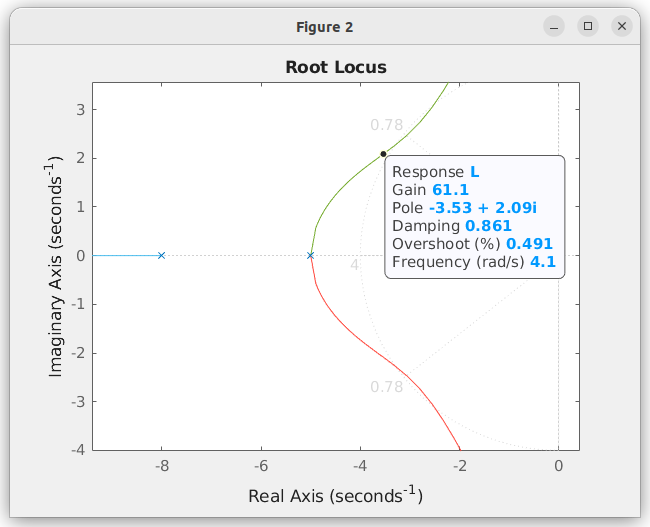

K = 61.1;

Close the loop and report the results.

T = feedback(K*L, 1);
damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.11e+00                 1.00e+00       1.11e+00         9.03e-01    
 -3.53e+00 + 2.09e+00i     8.61e-01       4.11e+00         2.83e-01    
 -3.53e+00 - 2.09e+00i     8.61e-01       4.11e+00         2.83e-01    
 -9.82e+00                 1.00e+00       9.82e+00         1.02e-01    


stepinfo(T)

ans = struct with fields:
         RiseTime: 1.9164
    TransientTime: 3.6743
     SettlingTime: 3.6743
      SettlingMin: 0.9025
      SettlingMax: 0.9984
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9984
         PeakTime: 5.9674


[pp, zz] = pzmap(T)

pp =   -9.8239 + 0.0000i
  -1.1072 + 0.0000i
  -3.5345 + 2.0880i
  -3.5345 - 2.0880i


zz = -3.0000

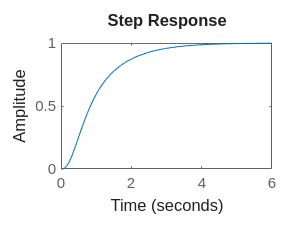

figure(3);
clf()
step(T)


$$D(s) = 61.1 \left( \frac{s+3}{s} \right)$$
